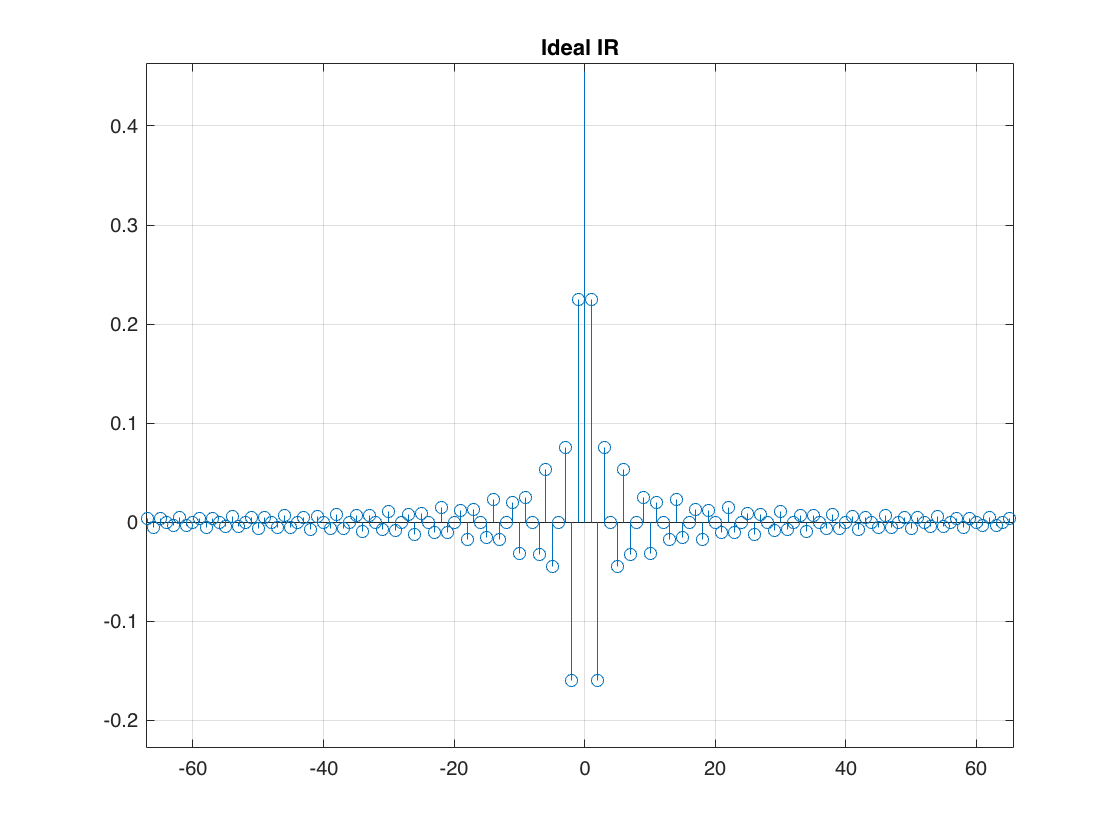

% Use windowed Fourier series method and design a FIR-type (causal) lowpass
% filter with cutoff frequency w_c = 3*pi/4.
% Impulse response of an ideal lowpass filter with cutoff frequency at w_c
% in matlab is w_c/pi*sinc(w_c/pi *n), where w_c = 2*pi*f_c/fs and 'n' is
% sample index.
clf;
fs = 8000;
n = (-70:70);
% h_d[n] = sin(3*pi/4*n) / (pi*n) = (3/4)*sinc(3/4*n)
h_d = 3/4*sinc(3/4*n);

figure(1)
stem(n,h_d)
title('Ideal IR')
grid on


M = 50;

## Finite Impulse Response filter?

#### Transfer function of a FIR filter is in the form:

#### 
$$H(z) = \frac{\sum_{k=0}^{2M} b_k z^{-k}}{1}$$


#### Where $b_i$ are the filter coefficients.

(Meaning that, e.g. in your last week's exercises only filter coefficient vector `b` would have values and vector `a` would be one.)

*Causality* means here simply that the filter only depends on previous and present inputs, not future.

## Windowing method?

#### 
$$H(n) = w(n) \cdot h(n)$$


### Where $w\left(n\right)$is the window function, and $h\left(n\right)$ the ideal impulse response (`h_d`)

## Task a)

generate 4th order FIR lowpass filter by windowing ideal impulse resonse with rectangular window: w_r[n] = 1, -M =< n =< M, M = 2 and else 0. Plot the impulse response and magnitude response


$$w_{\text{rect}}[n]  = 
\begin{cases}
1, \  n <= |M|\\
0, \ \text{otherwise}
\end{cases}$$


### Note that `n` goes here from -70 to 70, but `MATLAB` indicies start from 1!

### Once you have your window, remember to take only the wanted number of coefficients for your b vector

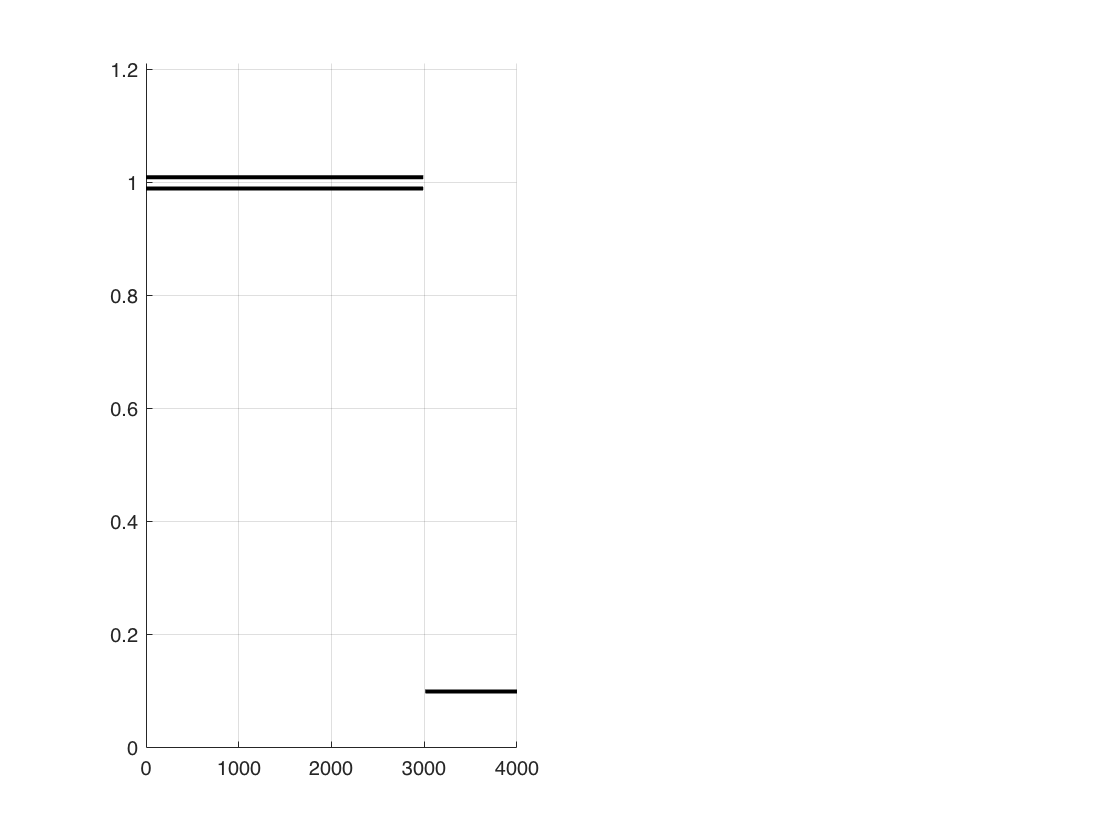

%Plot in linear graph
figure(2)
subplot(1,2,1)
%plot() here
hold on
speksitFIR([3/4*fs/2-10 fs/2*3/4+10], [1 0], [0.01 0.1], fs);
hold off
grid on

## Getting impulse and magnitude responses?

help impz

 impz Impulse response of digital filter
    [H,T] = impz(B,A) computes the impulse response of the filter:
 
                jw               -jw              -jmw
         jw  B(e)    b(1) + b(2)e + .... + b(m+1)e
      H(e) = ---- = ------------------------------------
                jw               -jw              -jnw
             A(e)    a(1) + a(2)e + .... + a(n+1)e
 
    given numerator and denominator coefficients in vectors B and A.
 
    [H,T] = impz(SOS) computes the impulse response of the filter specified
    using the second order sections matrix SOS. SOS is a Kx6 matrix, where
    the number of sections, K, must be greater than or equal to 2. Each row
    of SOS corresponds to the coefficients of a second order filter. From
    the transfer function displayed above, the ith row of the SOS matrix
    corresponds to [bi(1) bi(2) bi(3) ai(1) ai(2) ai(3)].
 
    [H,T] = impz(D) computes the impulse respo

help freqz

 freqz Frequency response of digital filter
    [H,W] = freqz(B,A,N) returns the N-point complex frequency response
    vector H and the N-point frequency vector W in radians/sample of
    the filter:
 
                jw               -jw              -jmw
         jw  B(e)    b(1) + b(2)e + .... + b(m+1)e
      H(e) = ---- = ------------------------------------
                jw               -jw              -jnw
             A(e)    a(1) + a(2)e + .... + a(n+1)e
 
    given numerator and denominator coefficients in vectors B and A.
 
    [H,W] = freqz(SOS,N) returns the N-point complex frequency response
    given the second order sections matrix SOS. SOS is a Kx6 matrix, where
    the number of sections, K, must be greater than or equal to 2. Each row
    of SOS corresponds to the coefficients of a second order filter. From
    the transfer function displayed above, the ith row of the SOS matrix
    corresponds to [bi(1) bi(2) bi

### The idea is to plot frequency response to the same plot as speksitFIR lines!

## Task b)

generate 4th order FIR lowpass filter by windowing ideal impulse resonse with Hamming window: w_h[n] = 0.54+0.46*cos(pi*n/M), -M =< n =< M, M = 2. Plot the impulse response and magnitude response


$$w_{\text{hamming}}[n]  = 
\begin{cases}
0.54+0.46 \cos \left( \frac{\pi n}{M} \right), \  n <= |M|\\
0, \ \text{otherwise}
\end{cases}$$


### Just modify your window generation, that's it!

% Plot in linear graph
subplot(1,2,2)
%plot() here
hold on
speksitFIR([3/4*fs/2-10 fs/2*3/4+10], [1 0], [0.01 0.1], fs);
hold off
grid on

## Task c)

Compare how the magnitude responses of the filters designed in (a) and (b) differ. Then do the same as in a) and b) but use filter order of 100 (M=50).